close all
clear all
clc

Abaixo estão as grandezas físicas do pêndulo:

M=1;
m=0.1;
l=0.4;
g=9.81;


Ts=0.1; %tempo de amostragem
T=10; %tempo de simulacao
dt=0.0001;
t=0:dt:T;
Nc=numel(t);
td=0:Ts:T;
Nd=numel(td);
%%
x=zeros(4,Nc);
u=zeros(Nd,1);
%%
Nr=Ts/dt;
kd=1;
fig = figure;
fig.Position = [0 0 1200 500];

Parametros PID

Kp =13;
Kd =1.4;
Ki = 0.4;


Ambiente de simulação

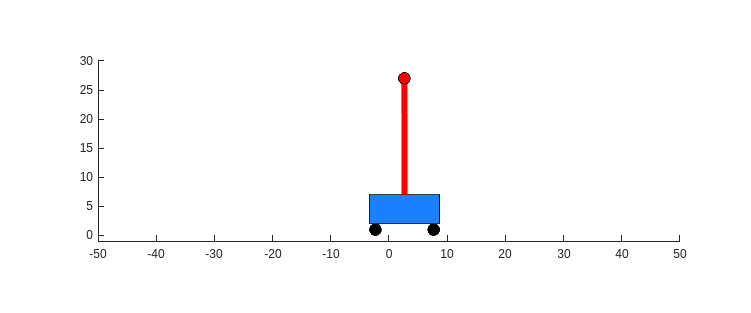

erro_anterior=0;
ui=0;
H=[1 0 0 0;...
   0 0 1 0];
%% condicao inicial
x(:,1)=[0 0 deg2rad(10) 0]';
pendulo=plotPendulo(x(:,1),fig);
for k=1:Nc-1
    %% simula modelo nao-linear pendulo em tempo continuo
    x(:,k+1)=pendulo_model(x(:,k),u(kd),dt,M,m,l);
    if (mod(k,Nr)==0 || k==1) && kd<=numel(td)
        %% simula controlador em tempo discreto
        if k~=1
            kd=kd+1;
        end
        y=H*x(:,k);
        px=y(1); %posicao na direcao x
        theta=y(2); %posicao angular
        %% calcula sinal de erro
        erro=0-theta; %erro de posicao angular
        %% Controle PID
        up=Kp*erro; %proporcional
        ud=Kd/Ts*(erro-erro_anterior); %derivativo (euler-backward)
        ui=ui+Ts*Ki*erro; %integrativo (euler-backward)
        u(kd)=up+ud+ui;
        erro_anterior=erro;

        %% atualiza frame da animacao 
        updatePendulo(x(:,k),pendulo);
        pause(0.05)
    end
end

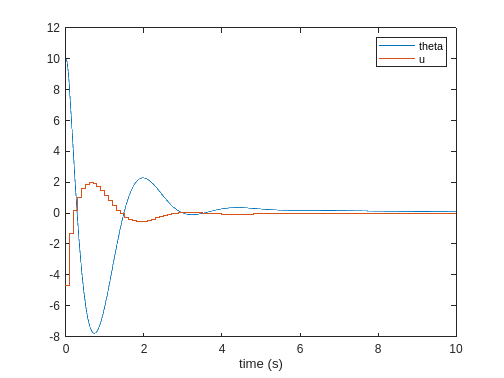

%%
figure
plot(t,rad2deg(x(3,:)))
hold on
stairs(td,u)
legend('theta','u')
xlabel('time (s)')

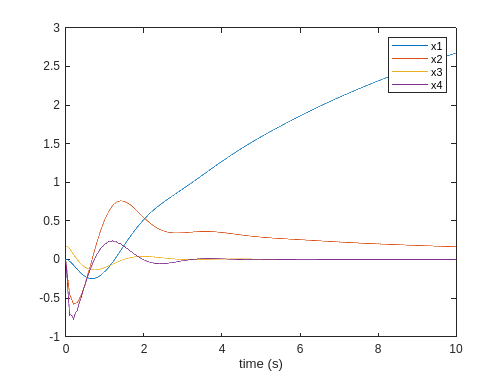

figure
plot(t,x')
legend('x1','x2','x3','x4')
xlabel('time (s)')